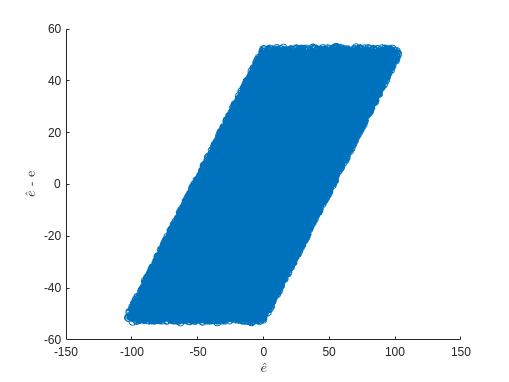

clear variables; close all; clc;
base_path = "/home/achadbo/XPlaneAutolandScenario";
err_path = base_path + "/errors";
plot_path = base_path + "/plots";
date = "/2024-4-23";
gen = "/generated_states.csv";
com = "/combined_states.csv";

csvData0_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-6-21/150/generated_states.csv");
csvData0_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-6-21/150/combined_states.csv");
error_NN_h_0 = csvData0_c.error_h;
error_NN_y_0 = csvData0_c.error_y;
y_0 = csvData0_c.y;
y_pred_0 = csvData0_g.y_err;
h_pred_0 = csvData0_g.h_err_NN;
x_0 = csvData0_c.x;
h_0 = csvData0_c.h;

% scatter3(h_0, x_0, y_0);
% hold on;
% xlabel("Height");
% ylabel("Dist from Runway");
% zlabel("Crosstrack Pos");
% hold off;
% 
% scatter(y_0, h_0);
% hold on;
% xlabel("Crosstrack Pos");
% ylabel("Height");
% hold off;
% 
% scatter(y_0, x_0);
% hold on;
% xlabel("Crosstrack Pos");
% ylabel("Dist from runway");
% hold off;
% 
% scatter(h_0, x_0);
% hold on;
% xlabel("Height");
% ylabel("Dist from runway");
% hold off;

csvData50_g = readtable(err_path + "/2024-5-24/50/generated_states.csv"); %50m, OOD by 0
csvData50_c = readtable(plot_path + "/2024-5-24/50/combined_states.csv");

error_h_50 = csvData50_c.error_h; %NN Error, height offset 
error_y_50 = csvData50_c.error_y; %NN Error, crosstrack offset 
ehat_h_50 = csvData50_g.h_err_NN; %NN Output- Predicted height offset
ehat_y_50 = csvData50_g.y_err;

scatter(error_h_50, ehat_h_50);
hold on;
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

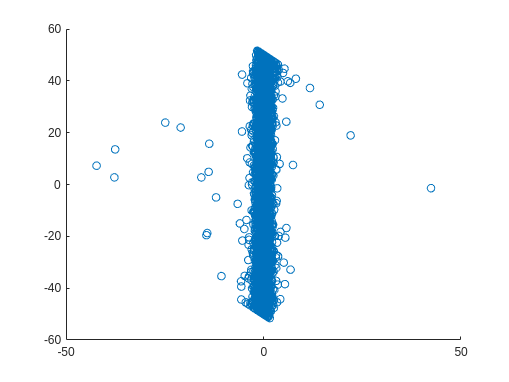


scatter(error_y_50, ehat_y_50);

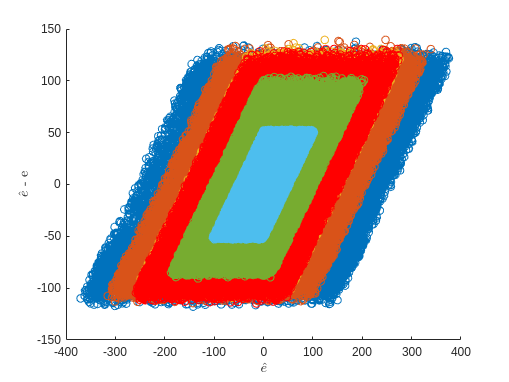


error_NN_h_50 = csvData50_c.error_h; %NN Error, height offset 
error_NN_y_50 = csvData50_c.error_y; %NN Error, crosstrack offset 
y_50 = csvData50_c.y;
y_pred_50 = csvData50_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_50 = csvData50_g.h_err_NN; %NN Output- Predicted height offset
h_true_50 = csvData50_g.h_err_true; %True height error based on state info 

%True State Information 
x50 = csvData50_c.x; %Horizontal distance from runway 
h50 = csvData50_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData100_g = readtable(err_path + date + "/100" + gen);%100m, OOD by 50
csvData100_c = readtable(plot_path + date + "/100" + com);

error_NN_h_100 = csvData100_c.error_h; %NN Error, height offset 
error_NN_y_100 = csvData100_c.error_y; %NN Error, crosstrack offset 
y_100 = csvData100_c.y;
y_pred_100 = csvData100_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_100 = csvData100_g.h_err_NN; %NN Output- Predicted height offset
h_true_100 = csvData100_g.h_err_true; %True height error based on state info 

%True State Information 
x100 = csvData100_c.x; %Horizontal distance from runway 
h100 = csvData100_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData150_g = readtable(err_path + date + "/150" + gen); %150m, OOD by 100
csvData150_c = readtable(plot_path + date + "/150" + com);

error_NN_h_150 = csvData150_c.error_h; %NN Error, height offset 
error_NN_y_150 = csvData150_c.error_y; %NN Error, crosstrack offset 
y_150 = csvData150_c.y;
y_pred_150 = csvData150_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_150 = csvData150_g.h_err_NN; %NN Output- Predicted height offset
h_true_150 = csvData150_g.h_err_true; %True height error based on state info 

%True State Information 
x150 = csvData150_c.x; %Horizontal distance from runway 
h150 = csvData150_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData200_g = readtable(err_path + date + "/200" + gen); %200m, OOD by 150
csvData200_c = readtable(plot_path + date + "/200" + com);

error_NN_h_200 = csvData200_c.error_h; %NN Error, height offset 
error_NN_y_200 = csvData200_c.error_y; %NN Error, crosstrack offset 
y_200 = csvData200_c.y;
y_pred_200 = csvData200_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_200 = csvData200_g.h_err_NN; %NN Output- Predicted height offset
h_true_200 = csvData200_g.h_err_true; %True height error based on state info 

%True State Information 
x200 = csvData200_c.x; %Horizontal distance from runway 
h200 = csvData200_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData250_g = readtable(err_path + date + "/250" + gen); %250m, OOD by 200
csvData250_c = readtable(plot_path + date + "/250" + com);

error_NN_h_250 = csvData250_c.error_h; %NN Error, height offset 
error_NN_y_250 = csvData250_c.error_y; %NN Error, crosstrack offset 
y_250 = csvData250_c.y;
y_pred_250 = csvData250_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_250 = csvData250_g.h_err_NN; %NN Output- Predicted height offset
h_true_250 = csvData250_g.h_err_true; %True height error based on state info 

%True State Information 
x250 = csvData250_c.x; %Horizontal distance from runway 
h250 = csvData250_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData300_g = readtable(err_path + date + "/300" + gen); %300m, OOD by 250
csvData300_c = readtable(plot_path + date + "/300" + com);

error_NN_h_300 = csvData300_c.error_h; %NN Error, height offset 
error_NN_y_300 = csvData300_c.error_y; %NN Error, crosstrack offset 
y_300 = csvData300_c.y;
y_pred_300 = csvData300_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_300 = csvData300_g.h_err_NN; %NN Output- Predicted height offset
h_true_300 = csvData300_g.h_err_true; %True height error based on state info 

%True State Information 
x300 = csvData300_c.x; %Horizontal distance from runway 
h300 = csvData300_c.h; %True Height (Altitude relative to runway) 

%=======================================================================
%=======================================================================

%2: Pinpoint the Graphs that we want to condense (Add photos of collected
%data from Notes to pdf) 
    %Most relevant graphs: 
        % Crosstrack Error NN vs Horizontal Distance from Runway 
        % Crosstrack Error NN vs True Height (Altitude relative to runway) 

        % Height Error NN vs Horizontal Distance from Runway 
        % Height Error NN vs True Height (Altitude relative to runway) 

    % Would be Interesting to explore (Not completed here) 
        % Crosstrack Error NN vs Predicted Crosstrack Offset (NN Output)
        % Height Error NN vs Predicted Height Offset (NN Output) 

%=======================================================================
%=======================================================================

%3: Create 3D scatter plots where x = distance, y = OOD and z = NN Error
%and condense 

%Fun Matrices: 
x = [x50; x100; x150; x200; x250; x300]; 
h = [h50; h100; h150; h200; h250; h300]; 
error_NN_h = [error_NN_h_50; error_NN_h_100; error_NN_h_150; error_NN_h_200; error_NN_h_250; error_NN_h_300];
error_NN_y = [error_NN_y_50; error_NN_y_100; error_NN_y_150; error_NN_y_200; error_NN_y_250; error_NN_y_300];
y_pred =  [y_pred_50; y_pred_100; y_pred_150; y_pred_200; y_pred_250; y_pred_300];
h_pred = [h_pred_50; h_pred_100; h_pred_150; h_pred_200; h_pred_250; h_pred_300];
h_true = [h_true_50; h_true_100; h_true_150; h_true_200; h_true_250; h_true_300];
zero = repelem(0, length(x50)); 
fifty = repelem(50, length(x100)); 
hundred = repelem(100, length(x150)); 
hundfif = repelem(150, length(x200)); 
weirdhundfif = repelem(150, length(csvData0_c.x)); 
twohun = repelem(200, length(x250)); 
twohunfif = repelem(250, length(x300)); 
ODD_m = [zero'; fifty'; hundred'; hundfif'; twohun'; twohunfif']; 

%Starting with the "most relevant"
%First we need to make a table for each plot (Doing this early in case it
%makes bounding easier)- it did not but I'll keep it in in case a blanket
%function is deemed appropriate 

% Crosstrack Error NN vs Horizontal Distance from Runway 
tab1 = table(x, ODD_m, error_NN_y);

% Crosstrack Error NN vs True Height (Altitude relative to runway) 
tab2 = table(h, ODD_m, error_NN_y);

% Height Error NN vs Horizontal Distance from Runway 
tab3 = table(x, ODD_m, error_NN_h);

% Height Error NN vs True Height (Altitude relative to runway) 
tab4 = table(h, ODD_m, error_NN_h);

%PLOTS + Condense 
%========================================================================================


scatter(error_NN_h_250, h_pred_250);
hold on; 
scatter(error_NN_h_200, h_pred_200);
scatter(error_NN_h_150, h_pred_150);
scatter(error_NN_h_0, h_pred_0, "red");
scatter(error_NN_h_100, h_pred_100);
scatter(error_NN_h_50, h_pred_50);

xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

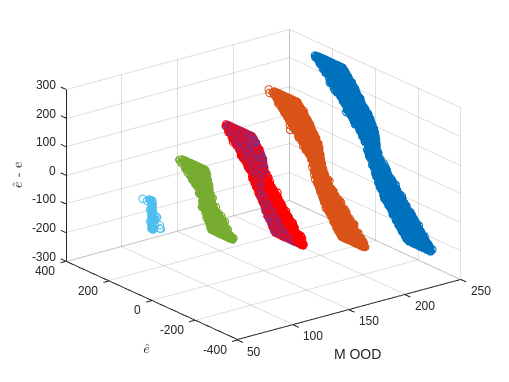





scatter3(twohunfif, error_NN_y_250, y_250);

hold on; 
scatter3(twohun, error_NN_y_200, y_200);
scatter3(weirdhundfif, error_NN_y_0, y_0, "red");
scatter3(repelem(150, length(csvData150_c.x)), error_NN_y_150, y_150);
scatter3(hundred, error_NN_y_100, y_100);
scatter3(fifty, error_NN_y_50, y_50);

xlabel("M OOD")
ylabel('$$\hat{e}$$','Interpreter','Latex');
zlabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

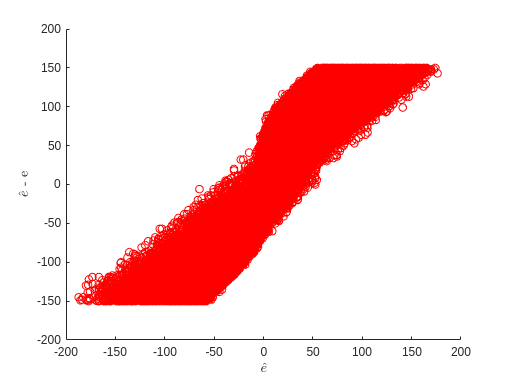




scatter(error_NN_y_0, y_0, "red");

hold on; 
%scatter(error_NN_y_250, y_250);
%scatter(error_NN_y_200, y_200);
%scatter(error_NN_y_150, y_150);
%scatter(error_NN_y_100, y_100);
%scatter(error_NN_y_50, y_50);
%axis([0 300 0 300])
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

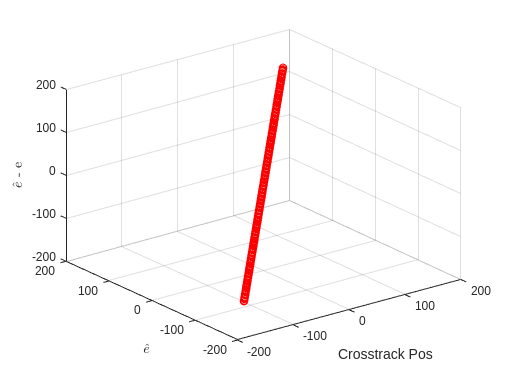


scatter3(y_0, error_NN_y_0, y_0, "red"); %Ask leahy
hold on;
xlabel("Crosstrack Pos")
ylabel('$$\hat{e}$$','Interpreter','Latex');
zlabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

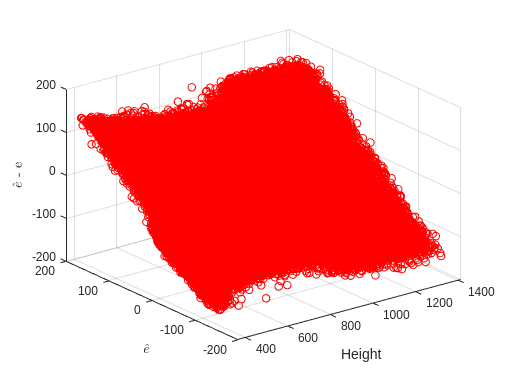


scatter3(h_0, error_NN_y_0, y_0, "red"); 
hold on;
xlabel("Height")
ylabel('$$\hat{e}$$','Interpreter','Latex');
zlabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

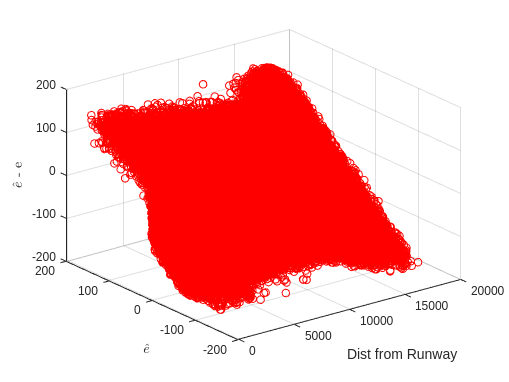


scatter3(x_0, error_NN_y_0, y_0, "red");
hold on;
xlabel("Dist from Runway")
ylabel('$$\hat{e}$$','Interpreter','Latex');
zlabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;